Aaron Cornelius

2020-9-24

### Problem 3.3

Compute the Jacobian of the SCARA manipulator in Figure 2.36.

The SCARA arm is functionally equivelent to a 3-link planar arm where $a_3$ is equal to zero and there is an additional, variable $d_3$ (this could also be inserted as an additional row between joints 2 and 3 for the 3-link arm, but this adds additional calculation steps.) Therefore, the D-H table for the SCARA arm is:

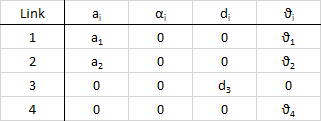

The transforms for each of the joints are thus:


$$\begin{array}{l}
A_0^1 \left(\vartheta_1 \right)=\left\lbrack \begin{array}{cccc}
c_1  & -s_1  & 0 & a_1 c_1 \\
s_1  & c_1  & 0 & a_1 s_1 \\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \\
A_1^2 \left(\vartheta_2 \right)=\left\lbrack \begin{array}{cccc}
c_2  & -s_2  & 0 & a_2 c_2 \\
s_2  & c_2  & 0 & a_2 s_2 \\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \\
A_2^3 \left(d_3 \right)=\left\lbrack \begin{array}{cccc}
c_3  & -s_3  & 0 & 0\\
s_3  & c_3  & 0 & 0\\
0 & 0 & 1 & d_3 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \\
A_3^4 \left(\vartheta_4 \right)=\left\lbrack \begin{array}{cccc}
c_4  & -s_4  & 0 & 0\\
s_4  & c_4  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack 
\end{array}$$


syms a_1 vartheta_1 a_2 vartheta_2 d_3 vartheta_4;
A01 = sym([cos(vartheta_1) -sin(vartheta_1) 0 a_1*cos(vartheta_1); ...
    sin(vartheta_1) cos(vartheta_1) 0 a_1*sin(vartheta_1); ...
    0 0 1 0; ...
    0 0 0 1]);
A12 = sym([cos(vartheta_2) -sin(vartheta_2) 0 a_2*cos(vartheta_2); ...
    sin(vartheta_2) cos(vartheta_2) 0 a_2*sin(vartheta_2); ...
    0 0 1 0; ...
    0 0 0 1]);
A23 = sym([1 1 0 0; ...
    1 1 0 0; ...
    0 0 1 d_3; ...
    0 0 0 1]);
A34 = sym([cos(vartheta_4) -sin(vartheta_4) 0 0; ...
    sin(vartheta_4) cos(vartheta_4) 0 0; ...
    0 0 1 0; ...
    0 0 0 1]);

p0 = sym([0;0;0]);
p1 = simplify(A01);
p1 = p1(1:3,4);
p2 = simplify(A01*A12);
p2 = p2(1:3,4);
p3 = simplify(A01*A12*A23);
p3 = p3(1:3,4);
p4 = simplify(A01*A12*A23*A34);
p4 = p4(1:3,4);

Therefore, computing the position vectors for each of the various links gives:


$$\begin{array}{l}
p_0 =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \\
p_1 =\left\lbrack \begin{array}{c}
a_1 c_1 \\
a_1 s_1 \\
0
\end{array}\right\rbrack \\
p_2 =\left\lbrack \begin{array}{c}
a_1 c_1 +a_2 c_{12} \\
a_1 s_1 +a_2 s_{12} \\
0
\end{array}\right\rbrack \\
p_3 =\left\lbrack \begin{array}{c}
a_1 c_1 +a_2 c_{12} \\
a_1 s_1 +a_2 s_{12} \\
d_3 
\end{array}\right\rbrack \\
p_4 =\left\lbrack \begin{array}{c}
a_1 c_1 +a_2 c_{12} \\
a_1 s_1 +a_2 s_{12} \\
d_3 
\end{array}\right\rbrack 
\end{array}$$


Next, the Z axis vectors for each joint are found. This is simple for the SCARA arm: they are all parallel with the base Z axis, since there are no $\alpha$ values in the DH table. Therefore:


$$z_0 =z_1 =z_2 =z_3 =z_4 =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$$


For the revolute joints 1, 2, and 4, the position section of the Jacobian can be calculated using the revolute portion of 3.30 $J_{P_i } =z_{i-1} \times \left(p_e -p_{i-1} \right)$, where $p_e$ is the position of the robot end effector, in this case at the end of joint 4. This calculation can be trivially performed for each joint:

cross(sym([0; 0; 1]), (p4-p0));
cross(sym([0; 0; 1]), (p4-p1));
cross(sym([0; 0; 1]), (p4-p2));
cross(sym([0; 0; 1]), (p4-p3));


$$\begin{array}{l}
J_{p_1 } =z_0 \times \left(p_4 -p_0 \right)=\left\lbrack \begin{array}{c}
-a_1 s_1 -a_2 s_{12} \\
a_1 c_1 +a_2 c_{12} \\
0
\end{array}\right\rbrack \\
J_{p_2 } =z_1 \times \left(p_4 -p_1 \right)=\left\lbrack \begin{array}{c}
-a_2 s_{12} \\
a_2 c_{12} \\
0
\end{array}\right\rbrack \\
J_{\mathrm{p4}} =z_3 \times \left(p_4 -p_3 \right)=\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack 
\end{array}$$


The prismatic joint 3 must be calculated using the prismatic portion of 3.30 $J_{p_i } =z_{i-1}$. Therefore:


$$J_{p_3 } =z_{i-1} =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$$


Next the orientation portion of the Jacobian is found. Again, the revolute portion of 3.30 ($J_{O_i } =z_{i-1}$) can be used to solve for joints 1, 2, and 4. This is trivial, since all the $z$ vectors are identical:


$$J_{O_1 } =J_{O_2 } =J_{O_4 } =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$$


The orientation portion of the Jacobian for the prismatic joint 3 is similarly trivial to calculate, since prismatic joints do not cause any rotation:


$$J_{O_3 } =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$$


All these results can be assembled into the final 4x6 Jacobian matrix:


$$J_P \left\lbrack \begin{array}{cccc}
-a_1 s_1 -a_2 s_{12}  & -a_2 s_{12}  & 0 & 0\\
a_1 c_1 +a_2 c_{12}  & a_2 c_{12}  & 0 & 0\\
0 & 0 & d_3  & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
1 & 1 & 0 & 1
\end{array}\right\rbrack$$


### Problem 3.11

Prove (3.64) in an alternative way, i.e., by computing $S\left(\omega_e \right)$ as in (3.6) starting from $R\left(\phi \right)$ in (2.18)

### Problem 3.12

With reference to (3.64) find the transformation matrix $T\left(\epsilon \right)$ in the case of RPY angles.

The Roll Pitch Yaw transformation is made of three rotations: roll ($R_1$), pitch ($R_2$), and yaw ($R_3$), defined by the following matrices:


$$\begin{array}{l}
R_1 \left(\vartheta_1 \right)=\left\lbrack \begin{array}{ccc}
\mathrm{cos}\left(\vartheta_1 \right) & -\mathrm{sin}\left(\vartheta_1 \right) & 0\\
\mathrm{sin}\left(\vartheta_1 \right) & \mathrm{cos}\left(\vartheta_1 \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack \\
R_2 \left(\vartheta_2 \right)=\left\lbrack \begin{array}{ccc}
\mathrm{cos}\left(\vartheta_2 \right) & 0 & \mathrm{sin}\left(\vartheta_2 \right)\\
0 & 1 & 0\\
-\mathrm{sin}\left(\vartheta_2 \right) & 0 & \mathrm{cos}\left(\vartheta_2 \right)
\end{array}\right\rbrack \\
R_3 \left(\vartheta_3 \right)=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \mathrm{cos}\left(\vartheta_3 \right) & -\mathrm{sin}\left(\vartheta_3 \right)\\
0 & \mathrm{sin}\left(\vartheta_3 \right) & \mathrm{cos}\left(\vartheta_3 \right)
\end{array}\right\rbrack 
\end{array}$$


Since it is the first rotation, the angular velocity vector for the first rotation$\left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack$ is simply along its rotation axis (Z) , $\left\lbrack \begin{array}{c}
\omega_{\mathrm{x1}} \\
\omega_{\mathrm{y1}} \\
\omega_z 1
\end{array}\right\rbrack =\dot{\vartheta_1 } \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$.

The second angular velocity vector is similar, but it's based on the new Y axis after rotation 1 has been applied:


$$\left\lbrack \begin{array}{c}
\omega_{\mathrm{x2}} \\
\omega_{\mathrm{y2}} \\
\omega_{\mathrm{z2}} 
\end{array}\right\rbrack =\dot{\vartheta_2 } \left(R_1 \left(\vartheta_1 \right)\cdot \left\lbrack \begin{array}{c}
0\\
1\\
0
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
-\mathrm{sin}\left(\vartheta_1 \right)\\
\mathrm{cos}\left(\vartheta_1 \right)\\
0
\end{array}\right\rbrack$$


Similarly, the third angular velocity vector is found by rotating the X axis rotation using the first two rotations:


$$\left\lbrack \begin{array}{c}
\omega_{\mathrm{x3}} \\
\omega_{\mathrm{y3}} \\
\omega_{\mathrm{z3}} 
\end{array}\right\rbrack =\dot{\vartheta_3 } \left(R_1 \left(\vartheta_1 \right)\cdot R_2 \left(\vartheta_2 \right)\cdot \left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
\mathrm{cos}\left(\vartheta_1 \right)\mathrm{cos}\left(\vartheta_2 \right)\\
\mathrm{cos}\left(\vartheta_2 \right)\mathrm{sin}\left(\vartheta_1 \right)\\
-\mathrm{sin}\left(\vartheta_2 \right)
\end{array}\right\rbrack$$


This is then assembled into the final transformation matrix:


$$T=\left\lbrack \begin{array}{ccc}
0 & -\mathrm{sin}\left(\vartheta_1 \right) & \mathrm{cos}\left(\vartheta_1 \right)\mathrm{cos}\left(\vartheta_2 \right)\\
0 & \mathrm{cos}\left(\vartheta_1 \right) & \mathrm{cos}\left(\vartheta_2 \right)\mathrm{sin}\left(\vartheta_1 \right)\\
1 & 0 & -\mathrm{sin}\left(\vartheta_2 \right)
\end{array}\right\rbrack$$


R01 = sym([cos(vartheta_1) -sin(vartheta_1) 0; sin(vartheta_1) cos(vartheta_1) 0; 0 0 1]);
R12 = sym([cos(vartheta_2) 0 sin(vartheta_2); 0 1 0; -sin(vartheta_2) 0 cos(vartheta_2)]);
R23 = sym([1 0 0; 0 cos(vartheta_3) -sin(vartheta_3); 0 sin(vartheta_3) cos(vartheta_3)]);

R01*[0 1 0]';
R01*R12*[1 0 0]';